clear

%costs and fitness of weibull-specified kernels
%stored in table all_w
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\cost_ben_model\nmax_0\weibull_MK.mat')
all_w = array2table([kernels out_mortcost out_kincost out_fitness],'VariableNames',{'v0','v1','v2','v3','v4','v5','Mortality','KinComp','Fitness'});
clear dist_fitness dist_kincost dist_mortcost kernels out_mortcost out_kincost out_fitness

%costs and fitness of nonparametric kernels
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\cost_ben_model\nmax_0\fitness_surface.mat')
%load('C:\Users\eschlatter\Dropbox\DispersalEvolution\cost_ben_model\weibull_MK.mat')
all = array2table([kernels out_mortcost out_kincost out_fitness],'VariableNames',{'v0','v1','v2','v3','v4','v5','Mortality','KinComp','Fitness'});


Last time we met, we were looking at one or two displacement kernels at a time -- e.g., from the start and end of 100000 generations of simulated kernel evolution. I'd compared total fitness, mortality cost, and kin competition cost among those two kernels. I found that, compared to a uniform kernel at the start of the simulation, the ESS kernel at the end had higher fitness, and that this was achieved by decreasing mortality cost at the expense of increased kin competition.

Based on our previous discussion, I wanted to look at how fitness, mortality, and kin competition were related over a wide range of kernels, rather than for just one or two kernels at a time.

#### 3D surface: mortality and kin competition vs fitness

First, I generated lots of kernels using a nonparametric approach. For now, I've reduced the number of distance bins in the kernel to 6 (0: staying home, 1: distance 1, ... , 5: distance 5).

To generate the kernels, I divided the total probability mass of 1 into twelfths. Every possible way to distribute those twelfths among the 6 bins is a kernel.

e.g. [12/12, 0, 0, 0, 0, 0] or [11/12, 1/12, 0, 0, 0, 0] or [1/12, 1/12, 1/12, 1/12, 1/12, 7/12], etc. In total, that's 6188 kernels.

For each kernel, I simulated one generation of dispersal and used it to calculate:

- mortality: the proportion of larvae that did not reach suitable habitat

- kin competition: the number of siblings a larva encounters, divided by its total number of siblings. (Note: this is a slight change from previously, when I used the total number of competitors as the denominator. The two quantities give similar results, because the habitat is symmetrical and saturated, but I think total number of siblings is more relevant to kin competition, and it's less sensitive to the population-level reproductive rate.)

- fitness: (1 - mortality) * (1 - kin competition)

On this plot, each kernel is represented by a blue dot. A surface is fit through them.

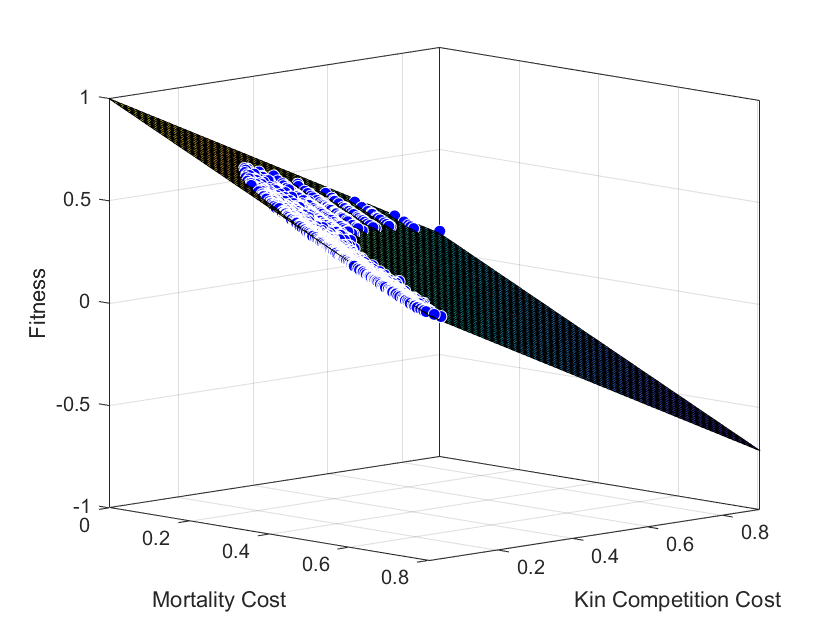

%% 3D surface: mort and kin comp vs fitness
f = fit([out_mortcost out_kincost],out_fitness,"poly11");
plot(f,[out_mortcost out_kincost],out_fitness)
xlabel('Mortality Cost')
ylabel('Kin Competition Cost')
zlabel('Fitness')
view([45.92 10.25])

The fitness surface is almost a flat plane. Based on the definitions, we know that fitness = 1 - mortality cost - kin competition cost + $\epsilon$, where:

$\epsilon = \sum_dv_dm_dk_d$, $v_d$ is the mass of the displacement kernel at distance d, $m_d$ is the mortality cost at distance d, and $k_d$ is the kin competition cost at distance d.

$\epsilon$ is quite small relative to the other quantities (at least for the seascape, etc. we're currently using), so the plane shown above is a pretty good fit through the points and is roughly described by: fitness = 1 - mortality - kin competition.

disp(f)

     Linear model Poly11:
     f(x,y) = p00 + p10*x + p01*y
     Coefficients (with 95% confidence bounds):
       p00 =       1.014  (1.012, 1.015)
       p10 =      -0.995  (-0.9969, -0.9931)
       p01 =      -1.027  (-1.03, -1.024)



[Question to look at some other time: how does the term $\epsilon$ change across the surface?]

#### 2D plot: mortality vs kin competition

Since the fitness surface is almost a plane, let's look at it in 2-d (mortality vs kin competition), instead of 3-d.

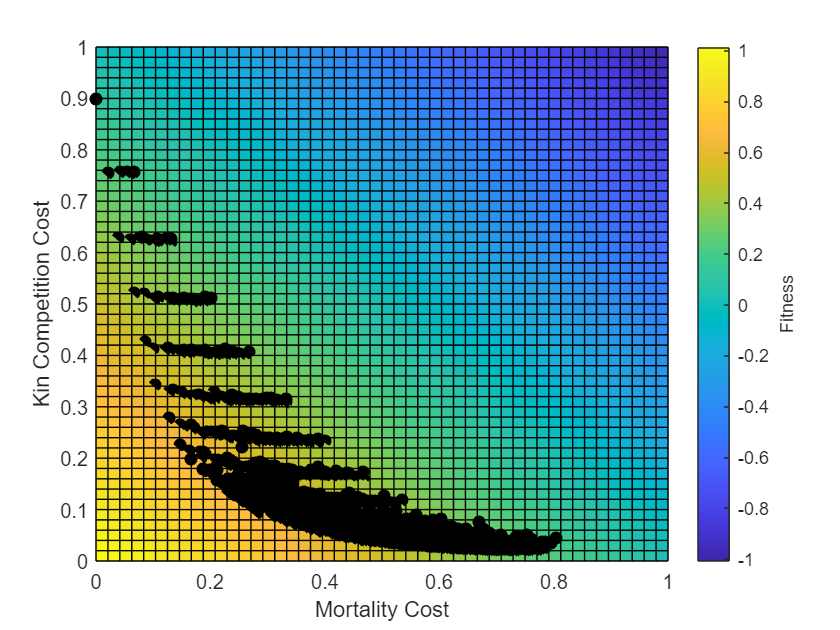

figure
clf
hold on
plot(f)
plot3(out_mortcost, out_kincost,out_fitness,'ok','MarkerFaceColor','k')
xlabel('Mortality Cost')
ylabel('Kin Competition Cost')
zlabel('Fitness')
view([0 90])
a = colorbar;
a.Label.String = 'Fitness';
hold off

There are only a limited number of combinations of mortality and kin competition that are possible -- i.e., no kernel has both near-zero mortality cost and near-zero kin competition cost. This constraint is set by the habitat and navigation ability. The kernels with the highest fitness (in the orange area of the plot) have intermediate levels of both costs.

#### Dissecting features of the mortality-kin competition plot

We can get an idea of what sorts of kernels lead to what points on the plot by looking at some patterns. In the figure below, the color of the points corresponds to the mass in the first bin of the kernel (i.e., staying home). 

e.g., the pink strip of dots around kin competition = 0.6 corresponds to all kernels with a 10/12 probability of staying home. The other 2/12 can be distributed among the remaining 5 bins in a variety of ways: ([10/12, 0, 1/12, 1/12, 0, 0]) or ([10/12, 0, 1/12, 1/12, 0, 0]) or ([10/12, 0, 0, 0, 0, 2/12]), etc. In any of these cases, since there are only 10 offspring per parent, only 1-2 siblings are likely to leave home, and they are unlikely to land in the same patch. So kin competition costs are roughly the same in all cases. Mortality costs, though, are greater for kernels with the 2/12 allocated to longer distances.

The point in the top left (mortality=0, kin competition ~ 0.9) is the kernel with all mass allocated to staying home.

The point near the bottom right (mortality > 0.8, kin competition ~ 0.025) is the kernel with all mass allocated to bin 6.

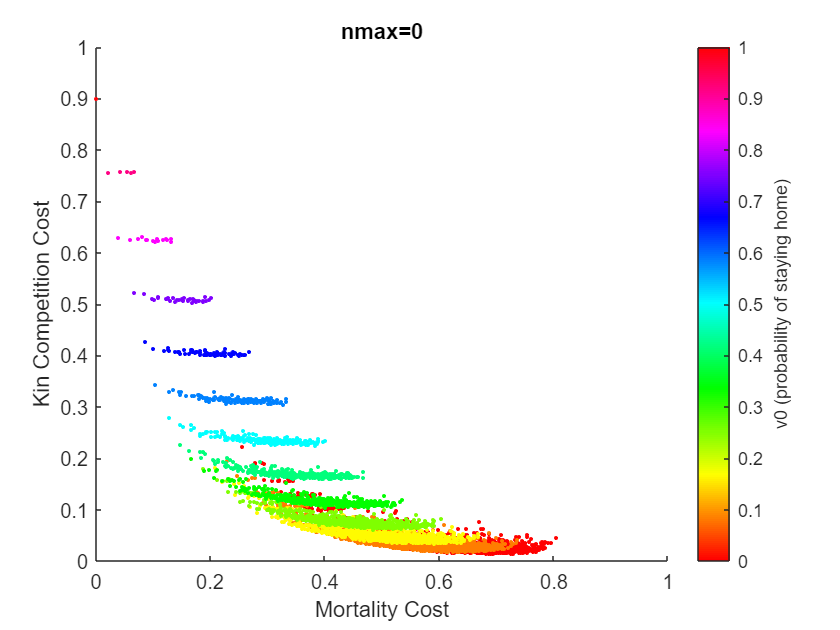

% scatterplot, with bands identified as constant v0
figure
scatter(all,'Mortality','KinComp','ColorVariable','v0','Marker','.')
colormap hsv
a = colorbar;
a.Label.String = 'v0 (probability of staying home)';
xlabel('Mortality Cost')
ylabel('Kin Competition Cost')
title('nmax=0')

We can also look at the mean of each kernel (represented by the colors of points in the plot below). Unsurprisingly, this is closely related to mortality cost. The greater the mean displacement distance, the greater the proportion of offspring that land in unsuitable habitat.

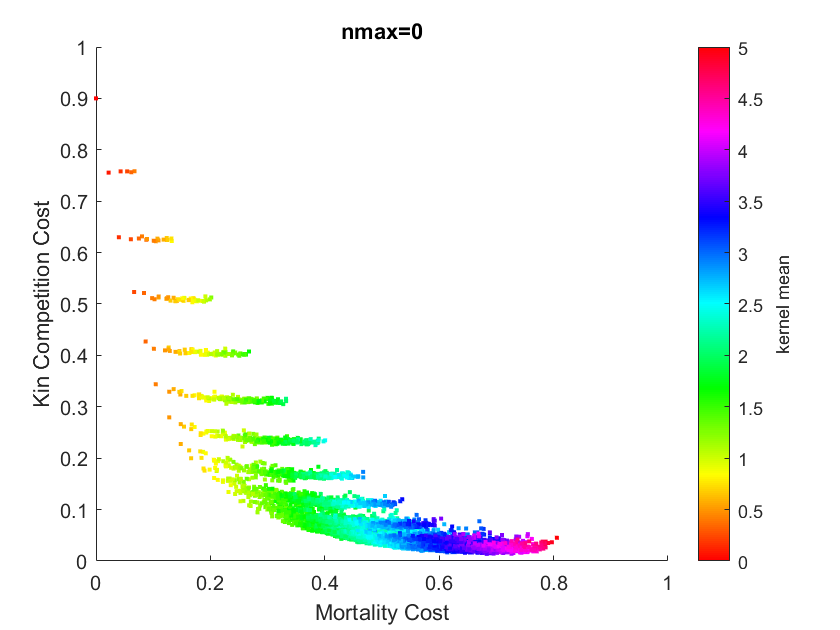

% scatterplot, points colored by kernel mean
mean_v = table2array(all(:,1:6))*(0:5)';
all2 = [all array2table(mean_v)];
figure
scatter(all2,'Mortality','KinComp','ColorVariable','mean_v','Marker','.')
colormap hsv
a = colorbar;
a.Label.String = 'kernel mean';
xlabel('Mortality Cost')
ylabel('Kin Competition Cost')
title('nmax=0')

% scatterplot, points colored by whether the kernel is monotone decreasing
monotone_v = zeros(size(all,1),1);
for i=1:size(all,1)
    mono = 1;
    for j=1:(size(kernels,2)-1)
        mono = mono*(kernels(i,j)>=kernels(i,j+1));
    end
    monotone_v(i)=mono;
end

allm = [all array2table(monotone_v)];
C = [1 0 0; 0 0 1];
figure
cmap = colormap(C)

cmap =      1     0     0
     0     0     1


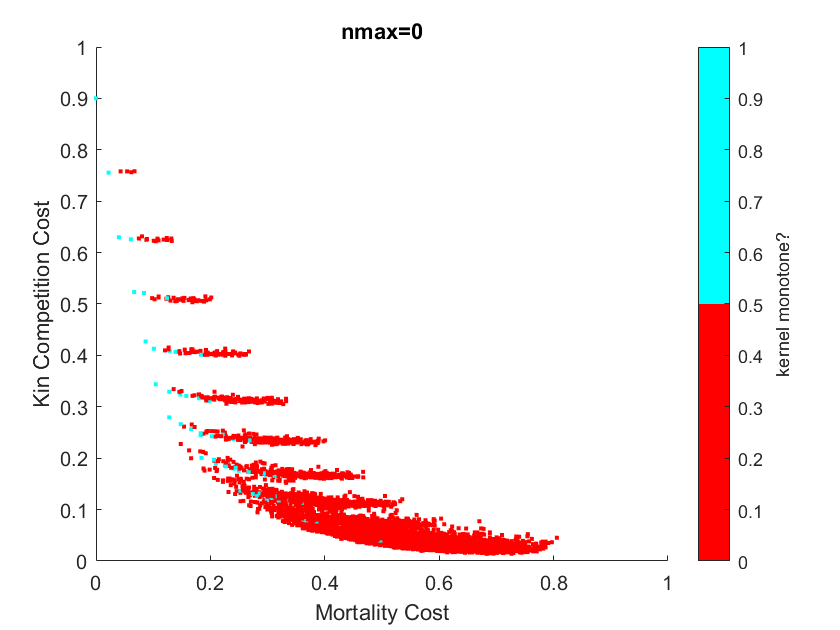

scatter(allm,'Mortality','KinComp','ColorVariable','monotone_v','Marker','.')
colormap hsv
a = colorbar;
a.Label.String = 'kernel monotone?';
xlabel('Mortality Cost')
ylabel('Kin Competition Cost')
title('nmax=0')



% scatterplot, points colored by kernel variance
% var_v = sum(((table2array(all(:,1:6))-(0.2*mean_v)).^2).*table2array(all(:,1:6)),2);
% all2 = [all2 array2table(var_v)];
% figure
% scatter(all2,'Mortality','KinComp','ColorVariable','var_v','Marker','.')
% %scatter3(all2,'Mortality','KinComp','Fitness','ColorVariable','var_v','Marker','.')
% colormap hsv
% a = colorbar;
% a.Label.String = 'kernel variance';
% xlabel('Mortality Cost')
% ylabel('Kin Competition Cost')
% title('nmax=0')

% % scatterplot, z dimension is kernel variance
% figure
% scatter3(all2,'Mortality','KinComp','mean_v','ColorVariable','var_v','Marker','.')
% colormap hsv
% xlabel('Mortality Cost')
% ylabel('Kin Competition Cost')
% title('nmax=0')
% odd_pt = [0.2306 0.1950];
% weird = all(ismember(table2array(all(:,7:8)),odd_pt,'rows'),:);

% % scatterplot, points colored by kernel variance, just a subset of points
% % (v0 = 0)
% figure
% scatter(all2(all2.v0==0,:),'Mortality','KinComp','ColorVariable','var_v','Marker','.')
% %scatter3(all2,'Mortality','KinComp','Fitness','ColorVariable','var_v','Marker','.')
% colormap hsv
% a = colorbar;
% a.Label.String = 'kernel variance';
% xlim([0 1])
% ylim([0 1])
% xlabel('Mortality Cost')
% ylabel('Kin Competition Cost')
% title('nmax=0')

% scatterplot, points colored by weibull parameter
% all2 = [all array2table(params)]; % first is lambda, second is k
% figure
% scatter(all2,'Mortality','KinComp','ColorVariable','params2','Marker','.')
% %scatter3(all2,'Mortality','KinComp','Fitness','ColorVariable','var_v','Marker','.')
% colormap hsv
% a = colorbar;
% a.Label.String = 'k';
% xlabel('Mortality Cost')
% ylabel('Kin Competition Cost')
% title('nmax=0')

#### Constraints

What combinations of mortality and kin competition are possible (i.e., what portions of the plane can be covered), given this seascape and navigation ability? We can roughly draw a line around the lower boundary. This line represents points where neither (mortality or kin competition) cost can be decreased without increasing the other.

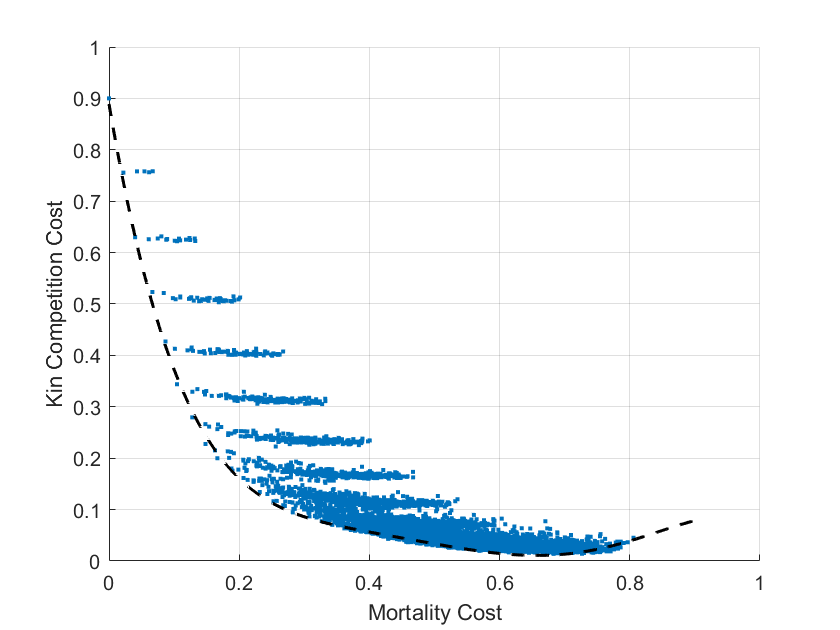

% first, pull out just the points at the edge
edgepoints = [];
nslice = 20;
for i=1:nslice
    start = (i-1)/nslice;
    finish = i/nslice;
    slice = all((all.Mortality>=start & all.Mortality<finish),:);
    minslice = slice((slice.KinComp==min(slice.KinComp)),:);
    edgepoints = [edgepoints ; minslice];
    clear start finish slice minslice
end

figure
clf
hold on
plot(out_mortcost,out_kincost,'.')
f = fit(edgepoints.Mortality,edgepoints.KinComp,"poly5");
% ep = plot(edgepoints.Mortality,edgepoints.KinComp,'o');
% ep.LineWidth = 1.5;
l = plot(f,'k');
l.LineWidth = 1.5;
l.LineStyle = '--';
xlabel('Mortality Cost')
ylabel('Kin Competition Cost')
grid on
legend off
hold off

I think our sample of kernels gives a good idea of where the boundaries of the shape should be. Additional kernels would fill in space between the existing points, but I don't think they'd push the outline at all. For example, I also generated a set of kernels using the Weibull distribution. Those are added to the previous plot as black points, below:

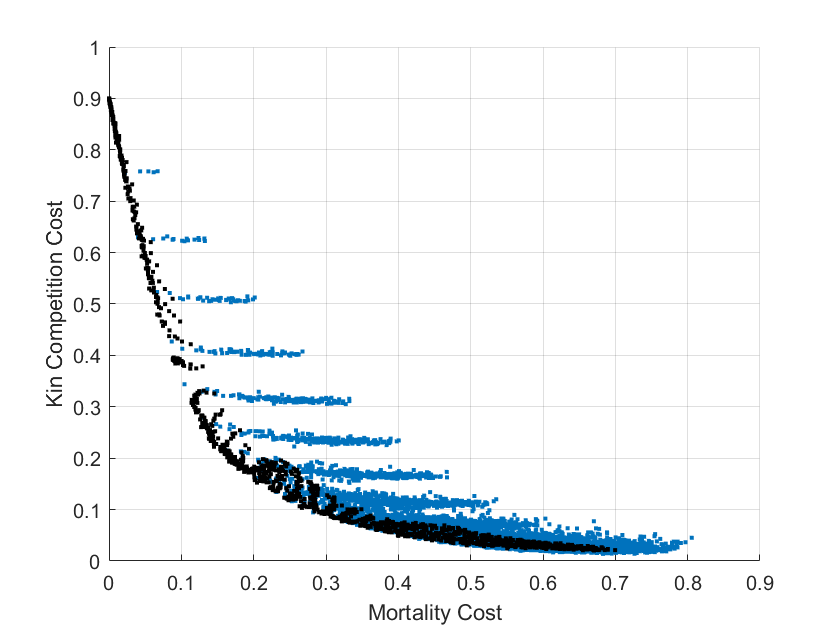

figure
clf
hold on
plot(out_mortcost,out_kincost,'.')
plot(table2array(all_w(:,"Mortality")),table2array(all_w(:,"KinComp")),'k.')
f = fit(edgepoints.Mortality,edgepoints.KinComp,"poly5");
% ep = plot(edgepoints.Mortality,edgepoints.KinComp,'o');
% ep.LineWidth = 1.5;
% l = plot(f,'k');
% l.LineWidth = 1.5;
% l.LineStyle = '--';
xlabel('Mortality Cost')
ylabel('Kin Competition Cost')
grid on
legend off
hold off

## Interactive plot -- look at kernels for each point

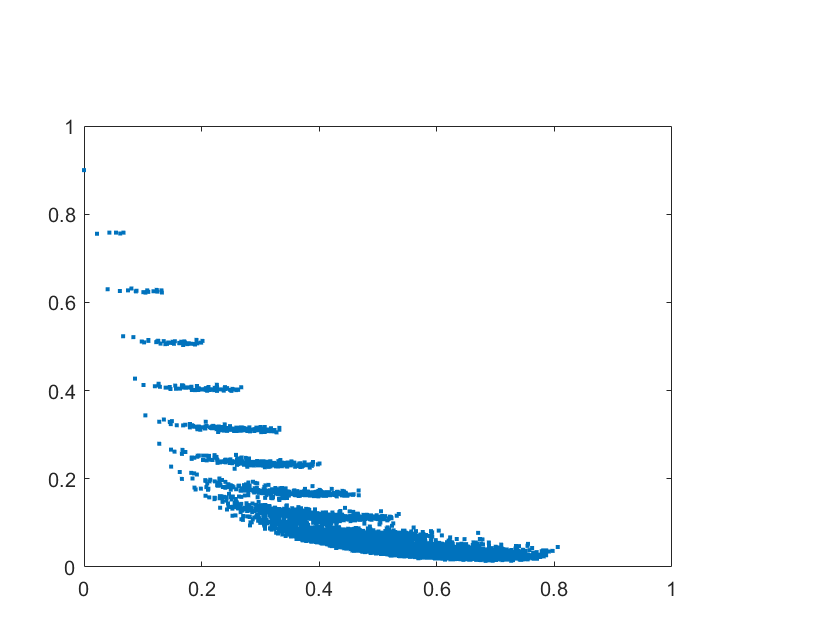

Error using ginput (line 84)
Interrupted by figure deletion

mk = [out_mortcost out_kincost];

f = figure;
ax1 = axes('Position',[0.1 0.1 0.7 0.7]);
xlabel(ax1,'Mortality Cost')
ylabel(ax1,'Kin Competition Cost')
plot(out_mortcost,out_kincost,'.')
for rep=1:30
g = ginput(1);
ax2 = axes('Position',[0.65 0.65 0.28 0.28]);
cla
D = pdist2(mk,g);
[~,ix] = min(D);
pt=mk(ix,:);
bar(0:5,kernels(ix,:),'k')
ylim([0 1])
end

f

#### Add a trajectory

Now we can look at the trajectory through this mortality-kin competition-fitness space as the kernel evolves. I simulated kernel evolution, starting with a uniform kernel, for 100 000 generations. I calculated mortality and kin competition costs at each generation. Then I plotted a trajectory, thinning to one point every 100 generations. The yellow circle is the starting point (uniform kernel), and the red circle is the ending point.

I'll want to run some more to check, but it seems like it draws a pretty straight line, at least up until the end. (Additional thought: if we can predict the evolutionary trajectory along this plane -- i.e., that it'll go in a straight line -- can we back-calculate to predict the evolutionary trajectory of the kernel?)

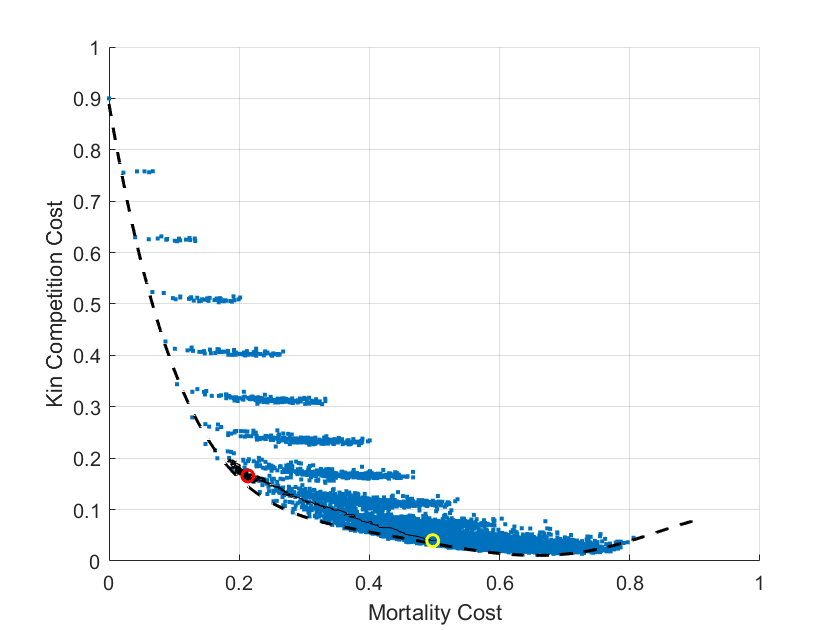

load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230331\IBM_bounded_sx=2_sy=512_nbins=6_nmax=0_del=0.001_b=10_p=1.mat')
mortcosts = sum(mortality_cost .* dtime_avg,2);
kincosts = sum(kincomp_cost .* dtime_avg,2);
fitnesses = mean((1-mortality_cost .* dtime_avg).*(1-kincomp_cost .* dtime_avg),2);
startpt = all(ismember(table2array(all(:,1:6)),(1/6)*[1 1 1 1 1 1],'rows'),:);

skip = 100; %increments to skip by
gens_to_use = skip*(1:(g/skip));

figure
hold on
plot(out_mortcost,out_kincost,'.')
f = fit(edgepoints.Mortality,edgepoints.KinComp,"poly5");
l = plot(f,'k');
l.LineWidth = 1.5;
l.LineStyle = '--';
plot(mortcosts(gens_to_use,:),kincosts(gens_to_use,:),'k')
plot(startpt.Mortality,startpt.KinComp,'o','Color','yellow','LineWidth',1.5)
plot(mortcosts(g),kincosts(g),'o','Color','red','LineWidth',1.5)
xlabel('Mortality Cost')
ylabel('Kin Competition Cost')
grid on
legend off
hold off

Here's the same figure, zoomed in on the ending. The trajectory seems to start out moving pretty straight, and then wanders around when it gets close to the end point.

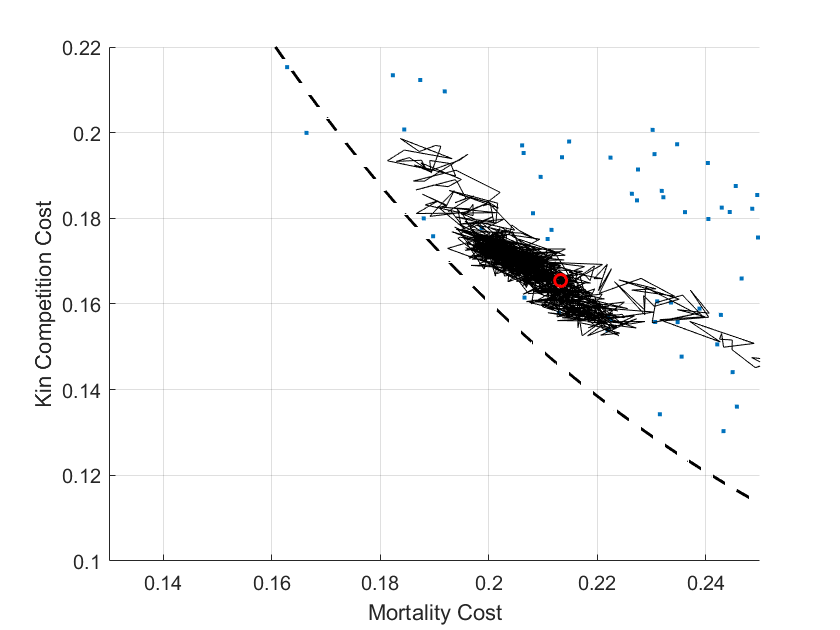

figure
hold on
plot(out_mortcost,out_kincost,'.')
f = fit(edgepoints.Mortality,edgepoints.KinComp,"poly5");
l = plot(f,'k');
l.LineWidth = 1.5;
l.LineStyle = '--';
plot(mortcosts(gens_to_use,:),kincosts(gens_to_use,:),'k')
plot(startpt.Mortality,startpt.KinComp,'o','Color','yellow','LineWidth',1.5)
plot(mortcosts(g),kincosts(g),'o','Color','red','LineWidth',1.5)
xlabel('Mortality Cost')
ylabel('Kin Competition Cost')
xlim([0.13 0.25])
ylim([0.1 0.22])
grid on
legend off
hold off

Remember that the way the plane is oriented in 3-d, a lot of the points in this region have similar fitness. So it makes sense we'd see some wandering around here.

My guess is that the pattern we see here (a relatively straight trajectory, up until the end) is what we would also see if we repeated this simulation, or if we used a different starting kernel. If we used a Weibull kernel in the simulation, instead of the currently implemented nonparametric version, I'd still expect to see the same thing.

% figure
% clf
% hold on
% plot3(out_mortcost, out_kincost,out_fitness,'.')
% plot3(mortcosts(gens_to_use,:),kincosts(gens_to_use,:),fitnesses(gens_to_use,:),'k')
% xlabel('Mortality Cost')
% ylabel('Kin Competition Cost')
% zlabel('Fitness')
% view([45.92 10.25])
% hold off

#### Next steps

From here, my proposed next steps are:

- Plot a few more trajectories with different starting kernels

- Possibly also plot some trajectories using the Weibull kernels. Now that I've tried using both parametric and nonparametric kernels, I'm not sure it makes much difference. The Weibull distribution reduces the number of parameters from 6 (one per bin) to 2, but the parameters don't affect the shape of the kernel in a way that's as intuitive as, say, a normal distribution. So I'm not sure how much we'd gain from that reduction in dimensionality.

- Repeat all of this for other navigation abilities. (This is nmax=0; I'm planning to look at nmax=1 and nmax=2.)

% %% Extra things I'm still playing around with
% 
% %% 3D surface: mort and kin comp vs fitness
% 
% plot3(out_mortcost,out_kincost,out_fitness,'.') % just points
% xlabel('Mortality Cost')
% ylabel('Kin Competition Cost')
% zlabel('Fitness')
% 
% f = fit([out_mortcost out_kincost],out_fitness,"poly11");
% disp(f)
% % fitness = 1 - mortcost - kincost
% % aka, total cost = total mort cost (weighted avg, over all distances)
% %                   + total kin cost (weighted avg over all distances)
% plot(f,[out_mortcost out_kincost],out_fitness)
% xlabel('Mortality Cost')
% ylabel('Kin Competition Cost')
% zlabel('Fitness')
% 
% % based on theory: fitness = 1 - mortcost - kincost + sum_d(v*m*k)
% sum_d_vmk = sum(kernels .* dist_mortcost .* dist_kincost,2,'omitnan');
% fitness_pred = sum_d_vmk + 1 - out_kincost - out_mortcost;
% histogram(out_fitness-fitness_pred) %precise and unbiased -- the variation is due to stochasticity
% fitness_pred2 = 1 - out_kincost - out_mortcost; %without that extra little term
% histogram(out_fitness-fitness_pred2) %without that extra little term, fitness is systematically underestimated (by a small amount)
% 
% % what's the deal with that little term? How does it vary with kernel?
% histogram(sum_d_vmk)
% % what kernels have the largest? The ones with the mass concentrated into
% % bins 1 and 2
% biggest_terms = all(sum_d_vmk>0.045,:);
% % what kernels have the smallest? The ones with most of their mass in bin
% % 0, and the rest distributed among other bins
% smallest_terms = all(sum_d_vmk<0.001,:);
% 
% rowss = kernels(:,1)==1/12;
% plot3(out_mortcost(rowss,:),out_kincost(rowss,:),sum_d_vmk(rowss,:),'.') % just points
% 
% f = fit([kernels(:,1) out_kincost],sum_d_vmk,"cubicinterp");
% plot(f,[kernels(:,1) out_kincost],sum_d_vmk)
% xlabel('Mortality Cost')
% ylabel('Kin Competition Cost')
% zlabel('Little term')
% 
% % identify kernels in a region of the surface
% stripe1 = all(out_kincost>0.8,:);
% stripe2 = all(out_kincost<0.7 & out_kincost>0.5,:);
% stripe3 = all(out_kincost<0.5 & out_kincost>0.3,:);
% 
% bestkernels = all(out_fitness>0.62,:);
% 
% % plot fitness vs kernel attributes
% kernel_mean = kernels*(1:6)';
% 
% f = fit([kernel_mean out_kincost],out_fitness,"poly11");
% plot(f,[kernel_mean out_kincost],out_fitness)
% xlabel('Kernel Mean')
% ylabel('Kin Competition Cost')
% zlabel('Fitness')
% 
